## Obstacle Avoidance

***Please save the Live Script after running your solution. It is mandatory to hand in the Solution along with the generated output for passing the assignment.***

*Please read the first pages of the Obstacle Avoidance Assignment (pdf) for a explanation of the VFH algorithm.*

*In the first part of the assignment (Tasks 1-10) you will implement the VFH algorithm and generate polarplots with the range readings, the obstacle density, the binary occupancy and the target, candidate and steering directions on the basis of static data (*`rangedata_caseX.mat`*) for each of the four cases of the VFH algorithm. Plotting should be done within the *`vfh`* function.*

*An example plot for case 2 is shown below. The range readings show the readings of a laser scanner mounted on the turtlebot from the center of the polarplot with a field of view of 240°. In this case there is a circular obstacle slightly right in front of the robot and otherwise free space, as indicated by the max range readings of 5. The obstacle density is computed (and optionally smoothed) and weighted according to the size of and the distance to the obstacle. By thresholding the obstacle density, we build a binary occupancy plot with free directions (here from 0° to 120° and from 240° to 310°) and directions that the robot should avoid (310° to 360°) from his current position. In the fourth plot, the targetdirection is shown in cyan. However, this direction is blocked by the obstacle. Four green candidate directions are computed by the VFH algorithm. The chosen candidate direction (the one closest to the target direction) is plotted in red.*

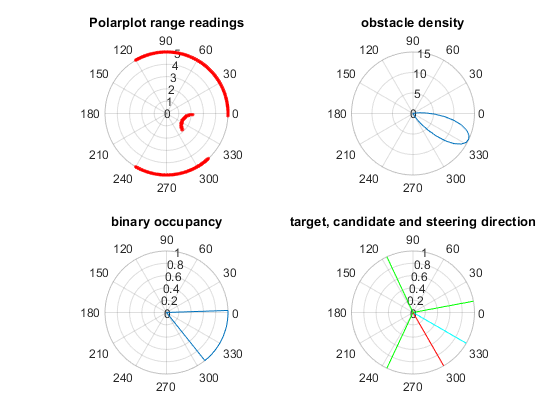

### Parameter definitions

% Your Parameter Definitions


### ***Obstacle Avoidance with the VFH Algorithm based on static range readings***

**1)** The static range data for testing your `vfh` function (implemented at the bottom of this script) is provided in the files `rangedata_caseX.mat`, where the `X` represents the case to test. Each data file contains an array of 683 range readings from a laser range sensor with a 240° field of view in the vectors `ranges` and `angles` as well as a target direction in `targetdir`. The files are uploaded to Moodle.

Load each of the four `rangedata_caseX.mat` files, create new figures and call the `vfh` function that you will implement in the next few tasks with each of the datasets. The goal is to create a figure with four polarplots similar to the example plot above for each of the four cases.

% Test case 1 ("Goal sector in selected valley")

% Test case 2 ("Goal sector not in selected non-narrow valley")

% Test case 3 ("Goal sector not in selected narrow valley")

% Test case 4 ("No candidate valley")


**Tasks 2)-10)** are guiding through the implementation of the `vfh` function at the bottom of this script.

### *Reactive obstacle avoidance with the VFH algorithm*

*In the following, we implement a reactive obstacle avoidance behavior based on the vector field histogram and determine an appropriate turn rate *$\omega$* that turns towards the desired steering direction and a safe linear velocity. *

*In cases 1-3 the robot moves at a constant forward velocity *$v=v_0$* unless the presence of obstacles demands safe motion at a reduced linear velocity. The regulation of the linear velocity follows a similar reasoning as the one for the primitive obstacle avoidance behavior in the lab Robotics Introduction Toolbox II. *

*In case 4 the robot stops and rotates in place (*$v=0$*, *$\omega =\omega_{\max }$*). Design an obstacle avoidance scheme that implements the basic vector field histogram methods in terms of a mapping between a laser range sensor (topic *`/scan`*) and the commanded velocities. The Turtlebot3 features the 360° laser distance sensor LDS-01. A sensor with a broad field of view has the advantage that oscillatory behaviours during wall following are avoided.*

*The goal pose in robocentric coordinates is obtained by mapping the navigation goal pose ( topic *`/move_base_simple/goal`*) into the robocentric frame *`base_link`* using the appropriate transform. The motion commands are published on the topic *`/cmd_vel`*.*

*For the regulation of the linear velocity reutilize the Matlab code for the simple reactive obstacle avoidance scheme from the assignment in the lab on Robotics Toolbox Introduction II or implement this behavior as described above. *

*A callback function determines the steering direction from the scan message by means of vfh. The steering direction is mapped onto the corresponding velocity command to be published on the topic /cmd_vel. The callback function obtains a reference to a *`PoseHandle`* object by which it reports the navigation goal pose in the robocentric frame back to the main program. The main loop governed by a rate object merely monitors progress towards the goal and terminates once the navigation goal is reached.*

*Launch the Turtlebot3 Gazebo simulation with the house map for the reactive Obstacle Avoidance.*

*For using the amcl Localization, a map of the environment is necessary. The map of the house environment is uploaded in Moodle. Download the map files (.yaml and .pgf), place them in ~/catkin_ws/src/turtlebot3/turtlebot3_navigation/maps/ and start the amcl Localization and rviz:*

*In case the robot gets stuck because it crashes into the environment, you can usually free the robot by moving the robot to a free location in the vicinity with the Translation Mode (shortcut T) in Gazebo. You need to restart the simulation, if you observe a wrong localization of the robot in rviz.*

**11)** Set the ROS_IP and ROS_MASTER_URI variables both in Matlab and Ubuntu for a more reliable transmission of messages.

Initialize ROS in Matlab (`rosinit`), initialize the ROS transformation tree (rostf) to later access the transform from `map` to `base_link` frame. 

Initialize parameters, subscribers and publisher and wait for an initial message on the topic `/move_base_simple/goal` to be invoked by the navgoal button in Rviz.

Initialize a publisher `velPub` for motion commands and a subscriber `navGoalSub` to monitor the navigation goal in RViz.

% rosinit

% setup tftree 

% setup publisher and subscribers


**12)** Reutilize the class `PoseHandle` in `PoseHandle.m` from the assignment Robotics System Toolbox I. The class is also uploaded to Moodle. The pose handle object has the properties $x$, $y$, and $\theta$ and should be instantiated as `goalPose`. 

Instantiate a Subscriber for the `\scan` Topic that triggers a function called `scanCallback` whenever a message is received. 

Use the following variables as arguments for the scanCallback function:

- velPub (for publishing computed `vfh` velocity commands)

- `navGoalSub (`for getting the latest navGoal messages`)`

- `tftree` (for transforming the latest `navGoal` messages to the base_link frame) 

- `goalPose` to the callback function (for storing the goalPose in robocentric coordinates for plotting in the main loop later)

% Initialize PoseHandle

% Initialize Subscriber for /scan function with a scanCallback function


**Tasks 13)-18)** are guiding through the implementation of the `scanCallback` function at the bottom of this script.

**19) **Test the VFH obstacle avoidance in the house environment and plot the path of the robot in a rated loop.

What are the limitations of VFH in terms of global navigation? Tune the parameters $\alpha$, $r_{\max }$, $h_{\max }$ of the VFH algorithm such that the robot safely traverses the gaps between the obstacles.

The plots generated within the `vfh` function are a handy tool for tuning the parameters. For tuning, you might want to stop sending the /`cmd_vel` message and place the robot at different locations with the Translation Mode (Shortcut T) in Gazebo.

% Initialize rate object

% implement rated loop in which the goalPose is plotted (hold on)

### ***Obstacle Avoidance with Advanced Vector Field Histogram Method***

**20)** **[Optional]** The Matlab Navigation toolbox provides an implementation of the advanced vector field histogram method in an object `controllerVFH`. Instantiate a vector field histogram object `vfhplus` and enable the direct use of `lidarScan` objects with

A lidarScan object can be directly constructed from incoming /scan messages:

The vfhplus object is associated with a function by the same name

that determines the steering direction. It has a similar signature as the function vfh that you implemented. Thus, you have to substitute the vfh function and the ranges and angles arguments by vfhplus and the scan object in your code. The controllerVFH object has similar parameters and properties as the basic vector field histogram approach.

- `NumAngularSectors` number of angular sectors in the histogram.

- `HistogramThresholds` thresholds for binary histogram computation specified as a two element vector. The two thresholds to determine the mapping from polar obstacle density to binary histogram. Polar obstacle densities higher than the upper threshold are represented as occupied space in the binary histogram. Densities smaller than the lower threshold are represented as free space. Densities that fall between the limits are set to the values in the previous binary histogram.

The VFH+ object has the following additional VHF+ specific parameters

- DistanceLimits upper and lower bounds for laser range readings. The range readings specified in equation 1 are considered only if they fall within the distance limits and ignored otherwise.

- RobotRadius : radius of the robot in meters

- SafetyDistance : safety distance around the robot. This is a safety distance to leave around the robot position in addition to RobotRadius. The robot radius and safety distance determine the obstacle-free direction in terms of rmax in equation 1.

- MinTurningRadius : minimum radius the robots drives as a curve

Inside your callback function scanCallback, instantiate an object `vhfplus` and setup its properties. Use a `bool` for switching with `if/else` between your `vfh` implementation and Matlabs `vfhplus` implementation

**21) [Optional] **The current velocity control (Task 17) of the robot relies on the computed `obstacleDensity` in driving direction, which is not available for Matlab's `vfhplus` implementation. Use Matlab's Helper Function `exampleHelperComputeAngularVelocity`, which is added at the bottom of this script for convenience, for computing the velocities commanded to the robot. Use the same `bool` as in the previous task for switching between the current velocity control and the velocity control for `vfhplus`.

**22)** **[Optional]** Evaluate the VFH+ approach for obstacle avoidance within House environment. Tune the parameters of VFH+ and compare the performance of VFH+ with your VFH implementation.

### **Function **`vfh`

**2)** Design a Matlab function 

that determines the steering direction of the robot according to the vector field histogram method. The input parameters `ranges` and `angles` denote the laser range data extracted from the `/scan` message. The input parameter `targetdir` denotes the heading towards the target in robocentric coordinates obtained from transforming the navigation goal message from the `map` frame to the `base_link` frame. The output parameter `steeringdirection` is the obstacle-free direction $\theta {\;}_{\textrm{ksol}}$ in robocentric coordinates based on the vector field histogram algorithm. Angles are specified in radians w.r.t. the robots current heading. 

Code and implement the function in a step by step manner following the instructions in the next tasks. 

Plot the range data with `polarplot` as illustrated in the upper left plot of the figure above. Set the output argument `steeringdirection` to `NaN` to indicate that no feasible steering direction is computed yet.

function [ steeringdirection, hc] = vfh(ranges, angles, targetdir)

    % Set steeringdirection to NaN
    
    % polarplot of the range readings (dependent on angles)
    

**3)** Convert the range data into a polar obstacle density histogram according to equation 


$$h_k =\sum_i \;{\left(1-\frac{r_i }{\;r_{\max } }\right)}^{\alpha \;} \;\;\textrm{with}\;\theta_i \in \left\lbrack \theta {\;}_k ,\theta {\;}_{k+1} \right\rbrack \;\textrm{and}\;r_{i\;} \in \left\lbrack 0,r_{\max } \right\rbrack \;\;\;\;\;\;\;\;\;\left(1\right)$$


from the laser range reading. Define internal parameters for `numsectors` = 90, `rmax` = 3, `alpha` = 1.5, `narrowthreshold` = 0.52 and `hmax=1`. Plot the histogram in a separate subfigure with `polarplot`.

- `numsectors`: Number of angular sectors in histogram. This parameter defines the number of bins in the histogram. 90 bins is a reasonable partition.

- `alpha`: This corresponds to the parameter $\alpha$ in the exponential in the equation above. Reasonable numbers are in the range [1.0, 2.0].

- `rmax`: This corresponds to the parameter rmax in equation (1) and denotes the maximal view range of the sensor. Reasonable numbers are in the range [0.5, 5.0].

- `narrowthreshold`: Threshold in radians to distinguish between a non-narrow candidate valley (case 2) and a narrow candidate valley (case 3). 0.17 corresponds to 10 degrees.

- hmax`:` Sectors with an obstacleDensity exceeding this threshold will be considered as occupied.

The code for histogram calculation is given in the assignment. Step through the following code, and try to understand the steps.You might want to try different parameters.

    % set parameters
    numsectors = 90;
    narrowthreshold = deg2rad(30); % angular range to declare narrow threshold (default: 30°)
    rmax  = 3;  % ignore obstacles beyond rmax;
    alpha = 1.5;  % exponential factor in eq(1)
    hmax  = 1;   % histogram threshold for occupancy
    
    % determine the sectorincrement as the angular separation of sectors and generate 
    % the array of sectormidpoints with linspace at equally spaced angular intervals 
    % and the sector_edges as the lower und upper bounds of the sector intervals.
    % given
    ranges = max(0, ranges);
    minangle = min(angles);
    maxangle = max(angles);
    sectorincrement = (maxangle-minangle)/numsectors;
    sectormidpoints = linspace(minangle, maxangle, numsectors);
    sector_edges = [sectormidpoints - sectorincrement/2, sectormidpoints(end) + sectorincrement/2];
    
    % filter the range data by selecting only the range data with ri < rmax using find.
    % given
    valididx = find(ranges < rmax);
    validranges = ranges(valididx);
    validangles = angles(valididx);
    
    % compute the vector of weightedranges from the validranges, rmax and alpha according to eq (1)
    % given
    weightedRanges = (1.0 - validranges/rmax).^alpha;
    
    % determine the association of angles to the sectors (sector_edges) with the function histcounts.
    % The function [N,edges,bin] = histcounts(X,edges)
    % sorts the data X into bins with the bin edges specified by the edges. The
    % output argument bin is an array of the same size as X whose elements are the
    % bin indices for the corresponding elements in X. In other words, bin(i) denotes
    % the index of the bin to which element X(i) belongs.
    [~,~,bin] = histcounts(validangles, sector_edges);
    
    % accumulate the vector of weightedranges in the polar density histogram obstacledensity of 
    % length numsectors according to eq (1) based on the array of bin indices bin.
    % given
    obstacleDensity = zeros(1, numsectors);
    for i = 1:length(bin)
        obstacleDensity(1, bin(i)) = obstacleDensity(1, bin(i)) + weightedRanges(i);
    end

**4) **Smoothen the polar obstacle density histogram `obstacleDensity` with the Matlab function `filtfilt.`

filters the input data x using a rational transfer function defined by the numerator and denominator coefficients b and a. The filtered output data is `y.` For a window size  of l = 2 the filter coefficients become $b = \frac{1}{7} [1, 2, 3, 2, 1]$ and $a=1$. 

Plot the smoothed polar obstacle density in a polarplot as shown in the top right plot of the figure above for the sample range data ranges and angles.

Return the first element of the `obstacleDensity` vector as `a `second output variable `hc `of the `vfh` function. `hc` corresponds to the `obstacleDensity` in driving direction and will be used later for computing the commanded velocity.

    % define filter parameters

    % filter obstacleDensity
    
    % return first element of filtered obstacleDensity as hc
    
    % polarplot of the filtered obstacleDensity (dependent on sectormidpoints)


**5)** Determine the logical array of occupied sectors `occupiedsectors` (non candidate valleys) with a polar density above the threshold $h>h_{\max }$ according to equation (3). Plot the occupied sectors for the sample range data `ranges` and `angles` in a separate subfigure with polarplot as shown in the figure at the top of this script.

    % find occupied sectors
    sectoroccupied = zeros(1,numsectors);  % boolean
    sectoroccupied(obstacleDensity > hmax) = true;
    
    % polarplot of sectoroccupied (dependent on sectormidpoints)
    

**6)** Determine the upper and lower indices of the nonoccupied sectors `~occupiedsector` with the function `diff` that detects transitions from occupied to nonoccupied sector. This code is given, try to understand the steps.

Afterward, `sectors(1,:)` contains the lower indices and `sectors(2,:)` the upper indices of free sectors.

    % given
    changes = diff([0 ~sectoroccupied 0]);   
    foundSectors = find(changes);
    
    % Because histogram is binary, the foundSectors will always have even elements.
    sectors = reshape(foundSectors, 2, []);
    sectors(2,1:end) = sectors(2,1:end) - ones(1, size(sectors, 2));

#### Handle different `vfh` cases

For evaluating the results of the implemented cases, plot the target direction, candidate directions, and steering direction calculated in the following tasks as shown in the fourth subplot of the figure above at the end of this function (Task 10). Lines in a `polarplot` can be plotted with:

**7)** Determine the target direction according to case 1:

Check whether the target direction `targetdir` is within the boundaries of any of the non occupied sectors (`~sectoroccupied`) with intervals computed according to the `sectormidpoints` and the upper and lower indices in `sectors`. In that case return `targetdir` as `steeringdirection`. 

Test your function for the sample range data `rangedata_case1.mat`. Call the `vfh` function with the data provided. The target direction given in the data is in a free sector such that the resulting steering direction should be the target direction. As an additional test you can vary the input target direction to an occupied direction and test if your function returns `NaN`.

    % Convert the indices of the free sectors to angles
    
    % Case 1: check if targetdirection is inside a free sector

**8)** Determine the target direction according to case 2:

Check which of the valleys are narrow sectors by estimating the valley width utilizing sector indices (`sectors`) and the `sectorincrement` and compare the width to the `narrowthreshold` parameter. For the non-narrow valleys generate one candidate direction at each boundary of the valley minus half of the `narrowthreshold`  to avoid that the `steeringdirection` is too close to a valley boundary. In the end select the candidate direction which is next to the target direction as final `steeringdirection`.

Test your implementation with the sample range data `rangedata_case2.mat`. Call the `vfh` function with the data provided.The result should consist of two non-narrow valleys, where the target direction is in an occupied sector. Hence four candidate directions should be estimated where the one next to the target direction is the output one.

    % find indices of narrow and non-narrow free sectors
    
    % Case 2: Compute two candidates for each non-narrow sector


**9)** Determine the target direction according to case 3:

For all valleys which are narrow only one candidate direction is generated. Each narrow candidate valley proposes a single candidate direction according to the `mid` that valley. Again the final steering direction is the candidate direction that is closest to `targetdir`. Plot the candidate directions, target direction and steering direction as shown in the figure above for the sample range data `ranges` and `angles` and for `targetdir` inside or outside free sectors. 

Test your implementation with the sample range data `rangedata_case3.mat`. Call the `vfh` function with the data provided.The result should consist of two non-narrow valleys on the most right and most left side and one narrow valley slightly right of the robot. In total five candidate directions should be generated in this scenario: Two for each non-narrow valley and one for the narrow valley. The final steering direction should be the one in the center of the narrow valley.

    % 8) Case 3: Compute one candidate direction for each narrow sector


**10)** Handle case 4:

If the set of candidate directions is empty, the `vfh` function returns the output parameter `steeringdirection = NaN`; 

To test this utilize `rangedata_case4.mat` where the robot is placed in a corner of the map.Call the `vfh` function with the data provided.

Make a `polarplot` (similar to the example plot at the top) containing the targetdir (in cyan), the steeringdirection (red), narrow candidate directions (blue) and non-narrow candidate directions (green).

    % Case 1: targetdir is free. targetdir becomes steeringdirection

    % Case 2 and 3: Narrow or Non-Narrow Valley. 
    % direction closest to the targetdir becomes steeringdirection

    % Case 4: Candidate directions are empty: steeringdirection becomes NaN
    
    % polarplot of the targetdir (cyan), 
    % steeringdirection (red), 
    % narrow candidate directions (blue) and
    % non-narrow candidate directions (green)

end

### Function `scanCallback`

**13)** Implement a callback function `scanCallback` that is called whenever a message on the `/scan` topic is received. The callback function determines the steering direction with help of the `vfh` algorithm. Steering direction and obstacle distance are mapped onto the corresponding motion command in terms of velocity and turn rate. Define maximum and minimum ranges for the turnrate $\omega \;$, linear velocity $v$, a goal radius $r_{\mathrm{goal}}$, and a controller gain $k_{\omega \;}$ for $\omega \;$. 

function [] = scanCallback( ~, scanMsg, velPub, navGoalSub, tftree, goalPose, varargin)

    % initialize parameters
        
    % check if latest navGoal message is available and return otherwise
    % with a message
    

**14)** Get the latest `navGoalMsg` and map it into the robocentric frame `base_link` with help of the corresponding `transform`. Extract the goal pose $x^{\left(r\right)}$, $y^{\left(r\right)}$, $\omega {\;}^{\left(r\right)}$ in robocentric coordinates with the helper function `[x,y,theta] = poseStampedMsg2Pose(poseMsg)` and assign it to the pose handle object `goalPose`. Convert the Cartesian target location x(r), y(r) into polar coordinates `targetDirection` and rho with `cart2pol`:

    % transform navGoal to the base_link frame

    % convert navGoalMsg to pose vector with PoseStampedMsg2Pose

    % convert navGoal pose to polar coordinates with cart2pol


**15)** Determine the robots `steeringdirection` for the current `targetDirection` and range data in `scanMsg` with help of the previously implemented function `vfh`.

    % Call vfh function to estimate steering direction


**16)** The designated steering direction $\theta_{k_{\textrm{sol}} } \;$ is mapped onto the turn rate $\omega \;$ according to


$$\omega =\textrm{sat}\left(k_{\;\omega \;} \;\theta_{k_{\textrm{sol}} } \right)$$


in which $\textrm{sat}$ is the saturation function that limits the turnrate to the interval $\omega \in \left\lbrack -\omega_{\max } ,\omega_{\max } \right\rbrack$

    % compute omega according to the equation above


**17)** To safely avoid collisions, the translational velocity is reduced with the proximity of obstacles. 

Let $h_c^{\prime }$ denote the smoothed polar obstacle density in the current direction of travel. Large values of $h_c^{\prime }$ indicate that either a large obstacle lies ahead or a smaller obstacle is close to the robot. Either case demands a sharp turn of the robot. This is achieved by a reduction of the linear velocity in order to allow completion of the turn towards the novel direction. The linear velocity is determined according to


$$v = v_0 \max(0,(1- h_c'/h_m))$$


and $h_m$ is an empirical parameter that achieves the desired reduction in speed by considering obstacle densities above $h_m$ as occupied sectors. The above control law reduces the linear velocity of the robot in anticipation of an steering maneuver. One might further consider that steering directions that deviate from the current robots heading require an ongoing turning. Thus, the linear velocity $v$ is reduced to $v_{\textrm{red}}$ in proportion to the turn rate


$$v_{red} = v (1- |\omega|/\omega_{max}) + v_{min}$$


in which $v$ denotes the linear velocity, $\omega_{\max }$ denotes the maximum admissible turn rate and $v_{\min }$ is a small non-zero velocity offset*.*

The robot can be stopped when approaching the goal pose, if the distance to the goal pose $\rho \;$is smaller than a predefined parameter $r_{\textrm{goal}}$:


$$v_{\mathrm{cmd}} =v_{\mathrm{red}} \frac{\rho \;\;}{r_{\mathrm{goal}} }\;\;\;\;\forall \;\;\rho <r_{\mathrm{goal}}$$


    % compute v_cmd according to the equations above


**18)** Instantiate an empty `velMsg` from the `velPub`, compose and publish the velMsg with the previously computed linear velocity $v$ and the angular turn rate $\omega \;$.

    % instantiate message for the /cmd_vel publisher, set v and omega and
    % publish the message (send)
    
end

### Helper Functions

function [ x, y, theta ] = PoseStampedMsg2Pose( poseMsg )
    % convert odometry message to vector
    x = poseMsg.Pose.Position.X;
    y = poseMsg.Pose.Position.Y;
    eul = quat2eul([poseMsg.Pose.Orientation.W poseMsg.Pose.Orientation.X  poseMsg.Pose.Orientation.Y poseMsg.Pose.Orientation.Z]);
    theta = eul(1);
end

%% For Task 20-22
function w = exampleHelperComputeAngularVelocity(steeringDir, wMax)
%EXAMPLEHELPERCOMPUTEANGULARVELOCITY Compute angular velocity
%   W = exampleHelperComputeAngularVelocity(STEERINGDIR)
%   returns the angular velocity W for a differential drive robot in radians
%   per second for a given steering direction STEERINGDIR in the robot's
%   coordinate frame in radians.
%
%   W = exampleHelperComputeAngularVelocity(STEERINGDIR, WMAX)
%   returns the angular velocity W for a differential drive robot in radians
%   per second for a given steering direction STEERINGDIR in the robot's
%   coordinate frame in radians and maximum angular velocity WMAX in
%   radians per second. The output angular velocity is saturated based on
%   the WMAX.
%
%   Example:
%       
%       w = exampleHelperComputeAngularVelocity(0.2, 1);

% Copyright 2015 The MathWorks, Inc.

%#codegen
%#ok<*EMCA>

% Allow variable input arguments
if nargin == 1   
    wMax = inf;
end

validateattributes(steeringDir, {'double'},{'real'},...
    'exampleHelperComputeAngularVelocity', 'STEERINGDIR', 1);
validateattributes(wMax, {'double'},{'real', 'positive'},...
    'exampleHelperComputeAngularVelocity', 'WMAX', 2);

% Computing in robot's coordinate frame
curPose = [0 0 0];

% The following computation is similar to robotics.PurePursuit
lookaheadPoint = [cos(steeringDir), sin(steeringDir)];
slope = atan2((lookaheadPoint(2) - curPose(2)), ...
    (lookaheadPoint(1) - curPose(1)));
alpha = angdiff(curPose(3), slope);

% Angular velocity command for a differential drive robot is
% equal to the desired curvature to be followed by the robot.

w = (2*sin(alpha));

% Pick a constant rotation when robot is facing in the opposite
% direction of the path
if abs(abs(alpha) - pi) < 1e-12
    w = sign(w)*1;
end

if abs(w) > wMax
    w = sign(w)*wMax;
end

end